fs=22050

fs = 22050



O_p = (2*4000)/fs;
O_s =(2*6000)/fs;
Rp = 0.1;
Rs = 30;

%generate order
%N is number of order
%O is angular freq
[N_but, O_n_but] = buttord(O_p,O_s,Rp,Rs);
[N_cheb1, O_n_cheb1] = cheb1ord(O_p,O_s,Rp,Rs);
[N_cheb2, O_n_cheb2] = cheb2ord(O_p,O_s,Rp,Rs);
[N_ell, O_n_ell] = ellipord(O_p,O_s,Rp,Rs);

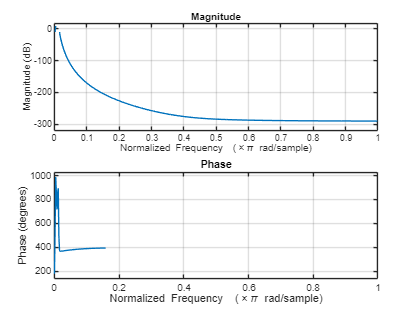

[n_but, d_but] = butter(N_but, O_n_but, 's');
[n_cheb1, d_cheb1] = cheby1(N_cheb1, Rp, O_n_cheb1, 's');
[n_cheb2, d_cheb2] = cheby2(N_cheb2, Rs, O_n_cheb2, 's');
[n_ell, d_ell] = ellip(N_ell, Rp,Rs, O_n_ell, 's');

%conecert to discrete time filter 
[b_bi_but, a_bi_but] = bilinear(n_but,d_but,fs);
[b_im_but, a_im_but] = impinvar(n_but,d_but,fs);


[b_bi_cheb1, a_bi_cheb1] = bilinear(n_cheb1,d_cheb1,fs);
[b_im_cheb1, a_im_cheb1] = impinvar(n_cheb1,d_cheb1,fs);


[b_bi_cheb2, a_bi_cheb2] = bilinear(n_cheb2,d_cheb2,fs);
[b_im_cheb2, a_im_cheb2] = impinvar(n_cheb2,d_cheb2,fs);

[b_bi_ell, a_bi_ell] = bilinear(n_ell,d_ell,fs);
[b_im_ell, a_im_ell] = impinvar(n_ell,d_ell,fs);


freqz(b_bi_but,a_bi_but)

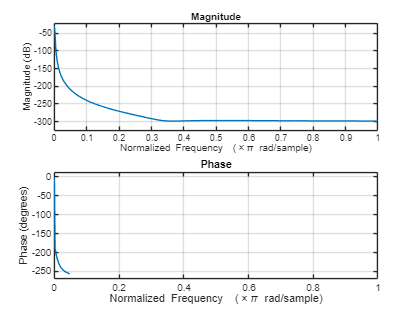

freqz(b_bi_cheb1,a_bi_cheb1)

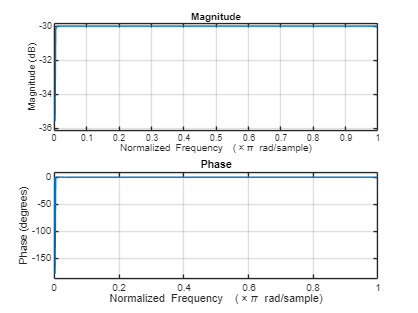

freqz(b_bi_cheb2,a_bi_cheb2)

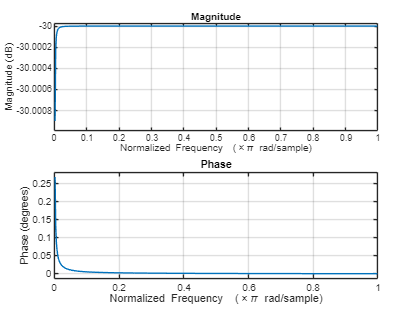

freqz(b_bi_ell,a_bi_ell)

fs=22050

fs = 22050

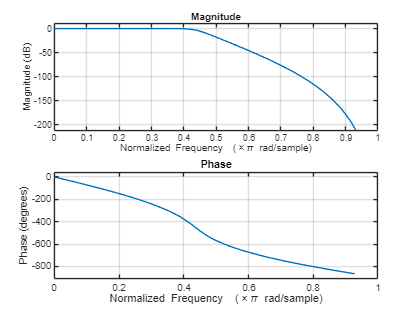



O_p = (2*4000)/fs;
O_s =(2*6000)/fs;
Rp = 0.1;
Rs = 30;



%generate order
%N is number of order
%O is angular freq
[N_but, O_n_but] = buttord(O_p,O_s,Rp,Rs);
[N_cheb1, O_n_cheb1] = cheb1ord(O_p,O_s,Rp,Rs);
[N_cheb2, O_n_cheb2] = cheb2ord(O_p,O_s,Rp,Rs);
[N_ell, O_n_ell] = ellipord(O_p,O_s,Rp,Rs);


%generate filter coefficients

[n_but, d_but] = butter(N_but, O_n_but);
[n_cheb1, d_cheb1] = cheby1(N_cheb1, Rp, O_n_cheb1);
[n_cheb2, d_cheb2] = cheby2(N_cheb2, Rs, O_n_cheb2);
[n_ell, d_ell] = ellip(N_ell, Rp,Rs, O_n_ell);

freqz(n_but, d_but)

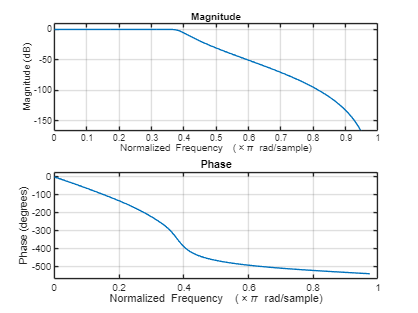

freqz(n_cheb1, d_cheb1)

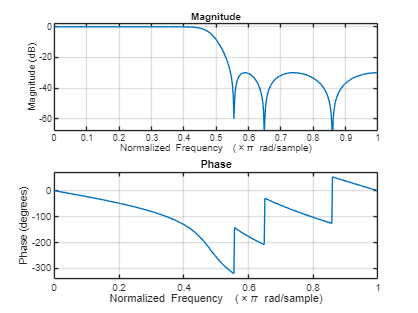

freqz(n_cheb2, d_cheb2)

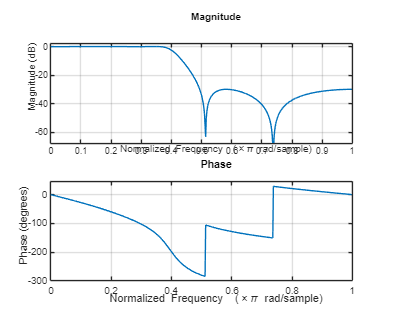

freqz(n_ell, d_ell)



fs=22050


O_p = (2*4000)/fs;
O_s =(2*6000)/fs;
Rp = 0.1;
Rs = 30;


%4



[x,Fs] = audioread('tononoise8mono.wav');
%generate order
%N is number of order
%O is angular freq
[N_but, O_n_but] = buttord(O_p,O_s,Rp,Rs);
[N_cheb1, O_n_cheb1] = cheb1ord(O_p,O_s,Rp,Rs);
[N_cheb2, O_n_cheb2] = cheb2ord(O_p,O_s,Rp,Rs);
[N_ell, O_n_ell] = ellipord(O_p,O_s,Rp,Rs);


%generate filter coefficients

[n_but, d_but] = butter(N_but, O_n_but);
[n_cheb1, d_cheb1] = cheby1(N_cheb1, Rp, O_n_cheb1);
[n_cheb2, d_cheb2] = cheby2(N_cheb2, Rs, O_n_cheb2);
[n_ell, d_ell] = ellip(N_ell, Rp,Rs, O_n_ell);

y= filter(n_cheb1, d_cheb1,x)

subplot(211)
specgram(x, 512, Fs, hanning(256), 128);
title('Original Spectogram')
subplot(212)
specgram(y, 512, Fs, hanning(256), 128);

title('Filtered Spectogram')


%X = freqz(y, 1, 512, Fs);
X = fft(y);

%plot(abs(X))



fs=22050

fs = 22050


O_p = (2*4000)/fs;
O_s =(2*6000)/fs;
Rp = 0.1;
Rs = 30;

%generate order
%N is number of order
%O is angular freq
[N_cheb1, O_n_cheb1] = cheb1ord(O_p,O_s,Rp,Rs);

%generate filter coefficients
[n_cheb1, d_cheb1] = cheby1(N_cheb1, Rp, O_n_cheb1);


% quantize cheby1 filter to round 2
n_cheb1_q = round(n_cheb1,2,'significant')

n_cheb1_q =     0.0031    0.0190    0.0470    0.0630    0.0470    0.0190    0.0031


d_cheb1_q = round(d_cheb1,2,'significant')

d_cheb1_q =     1.0000   -2.6000    3.9000   -3.6000    2.2000   -0.8100    0.1400


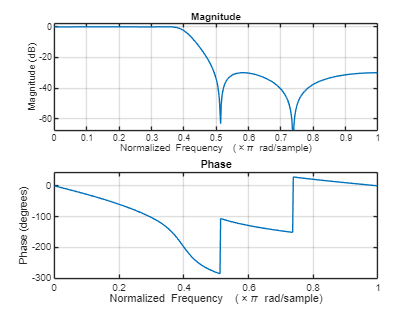


%plot frequency response and impulse response unquantized
subplot(211)

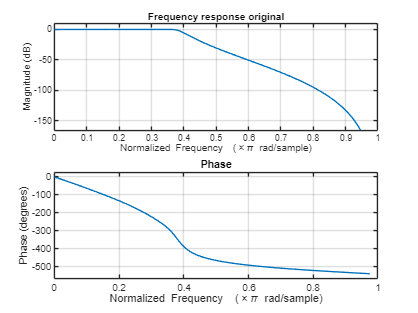

freqz(n_cheb1, d_cheb1)
title("Frequency response original")

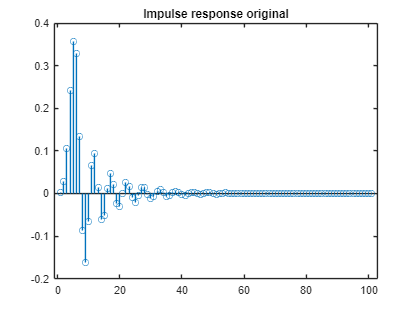




%impulse response 
input = [1, zeros(1,100)];

%filter signal 
y = filter(n_cheb1, d_cheb1,input);
stem(y)
title("Impulse response original")

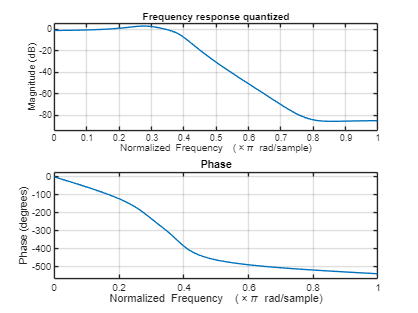


% %using impulse function
% sys = tf(n_cheb1, d_cheb1);
% impulse(sys);
% title("Impulse response original")

%plot frequency response and impulse response quantized 
subplot(212)
freqz(n_cheb1_q, d_cheb1_q)
title("Frequency response quantized")

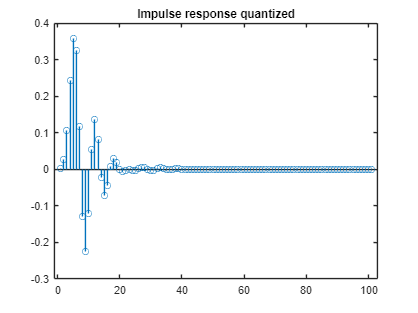


%impulse response 
input = [1 zeros(1,100)];
%filter signal 
y = filter(n_cheb1_q, d_cheb1_q,input);
stem(y)
title("Impulse response quantized")


% sys_q = tf(n_cheb1_q, d_cheb1_q);
%  impulse(sys_q);
%  title("Impulse response quantized")

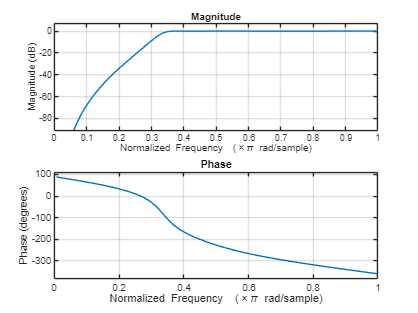

Fp = 4000;
Fs = 2000;
Rp = 0.1;
Rs = 30;
fs = 22050;

Wp = 2 * Fp / fs;
Ws = 2 * Fs / fs;

[N, Wn] = cheb1ord(Wp, Ws, Rp, Rs);
[b, a] = cheby1(N, Rp, Wn, "high");
freqz(b, a)

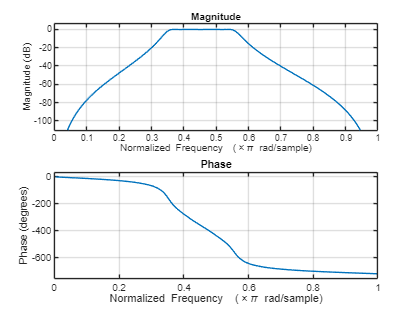


Fp = [4000 6000];
Fs = [2000 8000];
Rp = 0.1;
Rs = 30;
fs = 22050;

Wp = 2 * Fp / fs;
Ws = 2 * Fs / fs;

[N, Wn] = cheb1ord(Wp, Ws, Rp, Rs);
[b, a] = cheby1(N, Rp, Wn, "bandpass");
freqz(b, a)


Fp = [2000 8000];
Fs = [4000 6000];
Rp = 0.1;
Rs = 30;
fs = 22050;

Wp = 2 * Fp / fs;
Ws = 2 * Fs / fs;

[N, Wn] = cheb1ord(Wp, Ws, Rp, Rs);
[b, a] = cheby1(N, Rp, Wn, "stop");

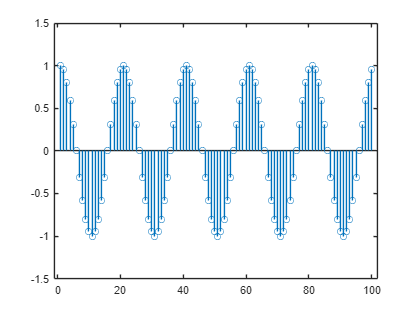

N=20;
b = [1 -cos(2*pi*(1/N))];
a = [1 -2*cos(2*pi*(1/N)) 1];

%number of samples 
n=100;

%impulse response 
input = [1 zeros(1,n-1)];
%filter signal 
y = filter(b,a,input);
stem(y)